% Tensor Component Analysis (TCA): via slice TCA
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
condition = ['BLA'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

data = EEG.data(:, :, epoch_trials);

% Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(data)); % Preallocate
for epoch = 1:size(data, 3)
    beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
end

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

pre_data = beta_signal(:, pre_idx,:); % ch x time x trial
post_data = beta_signal(:, post_idx,:); % ch x time x trial

% ——————————————————————————————————————————
% Step 1: save both tensors without concatenation
% ——————————————————————————————————————————
% ensure the subfolder exists
folder_to_save = fullfile(output_path, 'TCA', 'BLA');
if ~exist(folder_to_save, 'dir')
    mkdir(folder_to_save);
end

% build the full filename
output_file = fullfile(folder_to_save, 'tensor_data.mat');

% save your tensors and metadata
% save(output_file, 'pre_data', 'post_data', 'fs', 'time_vector');

function [U, S, V, metrics] = slicetca(X, R, options)
    % Implements Slice Tensor Component Analysis with error tracking
    % X: Input tensor (e.g., neurons x time x trials)
    % R: Number of components to extract
    % options: Additional parameters for optimization
    % metrics: Structure containing reconstruction error and explained variance

    % Default options
    if nargin < 3
        options = struct();
    end
    if ~isfield(options, 'max_iter'); options.max_iter = 100; end
    if ~isfield(options, 'tol'); options.tol = 1e-6; end
    if ~isfield(options, 'init'); options.init = 'random'; end

    % Get tensor dimensions
    dims = size(X);
    N_modes = ndims(X);
    
    % Calculate total variance of the data
    total_variance = sum(X(:).^2);
    
    % Initialize factor matrices
    if strcmpi(options.init, 'random')
        U = cell(N_modes, 1);
        for i = 1:N_modes
            U{i} = rand(dims(i), R);
            U{i} = U{i} ./ sqrt(sum(U{i}.^2, 1));
        end
    else
        % Custom initialization if provided
        U = options.init;
    end

    % Initialize metrics storage
    metrics.reconstruction_error = zeros(options.max_iter, 1);
    metrics.explained_variance = zeros(options.max_iter, 1);
    
    % Main alternating optimization loop
    prev_err = Inf;
    for iter = 1:options.max_iter
        % Update each factor matrix
        for n = 1:N_modes
            % Calculate Khatri-Rao product of all matrices except n
            idx = [n+1:N_modes 1:n-1];
            KR = U{idx(1)};
            for i = 2:N_modes-1
                KR = khatrirao(KR, U{idx(i)});
            end
            
            % Matricize the tensor X
            X_mat = tenmat(X, n);
            
            % Update factor matrix
            U{n} = X_mat.data * KR / (KR' * KR);
            
            % Normalize columns
            norms = sqrt(sum(U{n}.^2, 1));
            U{n} = U{n} ./ norms;
        end
        
        % Calculate reconstruction error using local cp_reconstruct
        X_est = cp_reconstruct_local(U);
        err = norm(X(:) - X_est(:))^2;
        
        % Calculate explained variance
        explained_var = 1 - (err / total_variance);
        
        % Store metrics
        metrics.reconstruction_error(iter) = err;
        metrics.explained_variance(iter) = explained_var;
        
        % Check convergence
        if abs(prev_err - err) < options.tol
            break;
        end
        prev_err = err;
    end
    
    % Trim metrics to actual iterations
    metrics.reconstruction_error = metrics.reconstruction_error(1:iter);
    metrics.explained_variance = metrics.explained_variance(1:iter);

    % Extract core tensor S and arrange factors
    S = zeros(R, R, R);
    for r = 1:R
        for modes = 1:N_modes
            tmp = X;
            for n = 1:N_modes
                tmp = tmprod_local(tmp, U{n}(:,r)', n);
            end
            S(r,r,r) = tmp;
        end
    end

    % For compatibility with matrix notation often used
    V = U{N_modes};
    U = U{1};
    
    % Local helper functions - defined within the scope of sliceTCA
    function X = cp_reconstruct_local(factors)
        % Reconstruct tensor from CP decomposition
        R = size(factors{1}, 2);
        
        % Get dimensions as a row vector
        dims = zeros(1, length(factors));
        for i = 1:length(factors)
            dims(i) = size(factors{i}, 1);
        end
        
        X = zeros(dims);
        
        for r = 1:R
            % Create component matrices
            component_matrices = cell(length(factors), 1);
            for n = 1:length(factors)
                component_matrices{n} = factors{n}(:,r);
            end
            
            % Calculate outer product
            temp = component_matrices{1};
            for n = 2:length(factors)
                temp = kron(temp, component_matrices{n});
            end
            
            % Add to the reconstruction
            X = X + reshape(temp, dims);
        end
    end

    function KR = khatrirao(A, B)
        % Khatri-Rao product
        [I, R] = size(A);
        [J, R] = size(B);
        
        KR = zeros(I*J, R);
        for r = 1:R
            KR(:,r) = kron(A(:,r), B(:,r));
        end
    end

    function B = tenmat(X, n)
        % Matricize tensor along mode n
        dims = size(X);
        N = ndims(X);
        
        % Permute dimensions to bring mode n to the front
        perm = [n, 1:n-1, n+1:N];
        Y = permute(X, perm);
        
        % Reshape to matrix
        B = struct();
        B.data = reshape(Y, dims(n), []);
        B.rdims = n;
        B.cdims = setdiff(1:N, n);
    end

    function Y = tmprod_local(X, U, n)
        % n-mode product of tensor X with matrix U
        sz = size(X);
        
        % Reshape X to matrix
        X_mat = reshape(X, sz(n), []);
        
        % Multiply
        Y_mat = U * X_mat;
        
        % Reshape back to tensor
        new_sz = sz;
        new_sz(n) = size(U, 1);
        Y = reshape(Y_mat, new_sz);
    end
end

% Set number of components
R = 3;

% Run Slice TCA
[U, S, V,metrics] = slicetca(pre_data, R);

% U will contain neuron factors
% S will contain core tensor
% V will contain trial factors

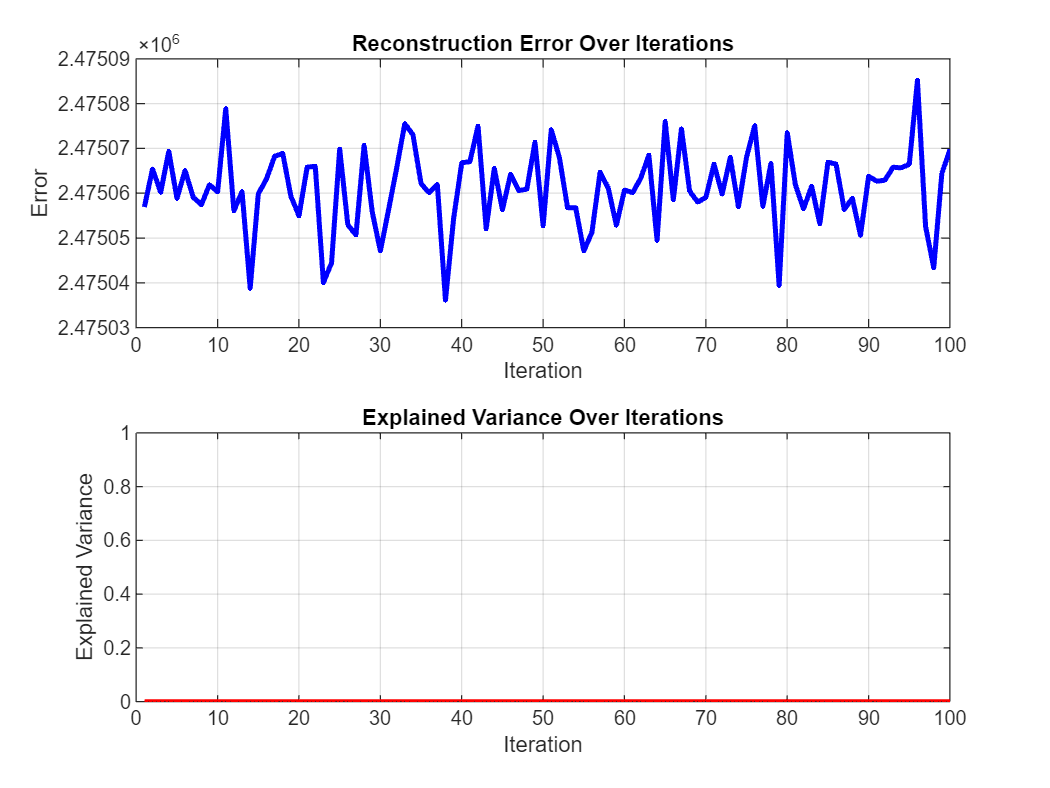

% Create a figure with two subplots
figure;

% Plot reconstruction error
subplot(2,1,1);
plot(metrics.reconstruction_error, 'b-', 'LineWidth', 2);
title('Reconstruction Error Over Iterations');
xlabel('Iteration');
ylabel('Error');
grid on;

% Plot explained variance
subplot(2,1,2);
plot(metrics.explained_variance, 'r-', 'LineWidth', 2);
title('Explained Variance Over Iterations');
xlabel('Iteration');
ylabel('Explained Variance');
ylim([0, 1]);
grid on;

% Evaluate different numbers of components
max_components = 50;
final_explained_variance = zeros(max_components, 1);
if isempty(gcp('nocreate'))
    parpool; % Uses default number of workers
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


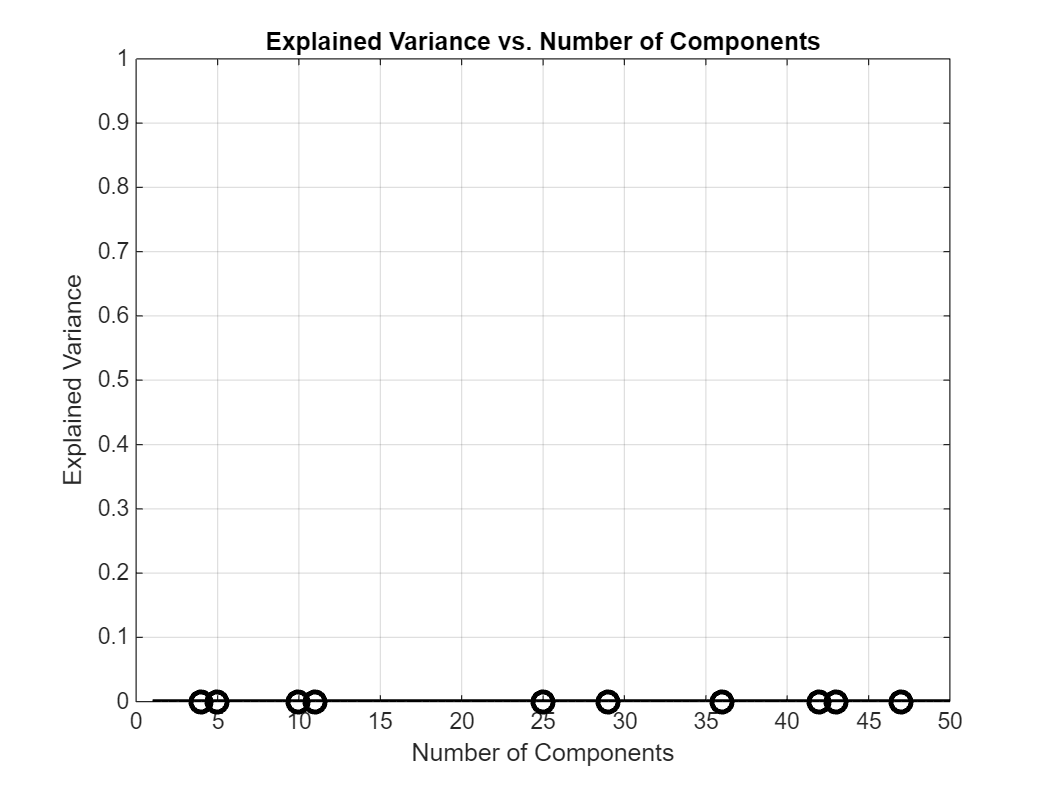


parfor r = 1:max_components
    [~, ~, ~, metrics] = sliceTCA(pre_data, r);
    final_explained_variance(r) = metrics.explained_variance(end);
end

% Plot explained variance vs. number of components
figure;
plot(1:max_components, final_explained_variance, 'ko-', 'LineWidth', 2, 'MarkerSize', 8);
title('Explained Variance vs. Number of Components');
xlabel('Number of Components');
ylabel('Explained Variance');
ylim([0, 1]);
grid on;